# Power Spectral Density Analysis

- Get the power spectral of each sample pair (i.e sick & normal)

- Sum the spectra of each class's (i.e sick & normal) channel across subjects. Also get the vector of the total power in all the channels (i.e sum all the channels)

- Plot the spectra of the relative power in each channel

- Plot the average power of each channel when summed across samples

- Plot average power of each class by using the previous results

For this code you need to change the directories of your trial to traget the right **dataset** and **sample extraction method**. In this case there are two datasets:-

- **Kfold_roi**: which includes ERP epoches

- **Kfold_pruned**: Epoches from continues EEG data

There are also two extraction methods:-

- Activation Maximization

- Sorting

# This is for sorted sample method

## Calculate the relative power of each participant for the 4 regions

clear;
dataset_type = 'roi';
load(['C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_', dataset_type ,'\trial6\sorting\matrix_jitter_output.mat']);
srate = 250;
nfft = srate;
f_length = (nfft/2) + 1;
participant_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest
f_channels = [4, 5, 6, 7, 8] - 3; % Frontal channels
c_channels = [9, 10, 11, 12, 13] - 3; % Central channels
p_channels =  [14, 15, 16] - 3; % Parietal channels
o_channels = [17, 18, 19] - 3; % Occipital channels

c_regions = {f_channels, c_channels, p_channels, o_channels};
region_index = {'r1', 'r2', 'r3', 'r4'}; % The region IDs used in the 'p' structure
condition_index = {'true_sick','true_normal', 'false_sick', 'false_normal'}; % The condition IDs used in the 'p' structure

empty_array = [];

% Create the structure
for i = 1:participant_no
    p(i).true_sick.r1 = empty_array;
    p(i).true_sick.r2 = empty_array;
    p(i).true_sick.r3 = empty_array;
    p(i).true_sick.r4 = empty_array;
    
    p(i).true_normal.r1 = empty_array;
    p(i).true_normal.r2 = empty_array;
    p(i).true_normal.r3 = empty_array;
    p(i).true_normal.r4 = empty_array;
    
    p(i).false_sick.r1 = empty_array;
    p(i).false_sick.r2 = empty_array;
    p(i).false_sick.r3 = empty_array;
    p(i).false_sick.r4 = empty_array;
    
    p(i).false_normal.r1 = empty_array;
    p(i).false_normal.r2 = empty_array;
    p(i).false_normal.r3 = empty_array;
    p(i).false_normal.r4 = empty_array;
end

%loop through each participant
for participant = 1:participant_no
    fieldName = ['field', num2str(participant)];
    %loop through each condition
    for condition = 1:length(condition_index)
        % Check if the condition is not empty (Has no samples)
        if ~isempty(export_matlab.(fieldName).(condition_index{condition}))
            % Get the samples if the respective condition
            samples = export_matlab.(fieldName).(condition_index{condition}); % 16X250X10 Channels X srate X Samples

            % Calculate the relative power of the samples
            % The relative power of the mean power of the samples is
            % calculated here
            [sp, fq] = relativePower(samples, window_length, overlap_length, nfft, srate, f_length); % Channels X nfft
            %loop through each region
            for region = 1:length(region_index)
                region_channels = sp(c_regions{region}, :); % Get the power of the channels in the respective region
                % Get the relative power in the region
                % The power is divided by the number if channels to account
                % for the different number of channels in a region
                p(participant).(condition_index{condition}).(region_index{region}) = sum(region_channels,1) / size(region_channels,1);
            end
        end
    end
end

## Get The Relative Power For The 4 Conditions

f = (0:1:40); % Frequencies of interest

% ARRAY TO HOLD SAMPLES
true_sick_array = []; % 16x250xM here M is the number of samples 
true_normal_array = []; % 16x250xM here M is the number of samples 
false_sick_array = []; % 16x250xM here M is the number of samples 
false_normal_array = []; % 16x250xM here M is the number of samples 

for participant = (1:participant_no)

    % GET THE SAMPLES
    % Get the best sick and normal samples
    true_sick_sample = cell2mat(struct2cell(p(participant).(condition_index{1})));
    true_normal_sample = cell2mat(struct2cell(p(participant).(condition_index{2})));

    % Get the worst sick and normal samples
    false_sick_sample = cell2mat(struct2cell(p(participant).(condition_index{3})));
    false_normal_sample = cell2mat(struct2cell(p(participant).(condition_index{4})));

    % GET THE SPECTRAS
    % Get the best spectra and their respective frequncies for both classes
    if ~isempty(true_sick_sample)
      if ~isempty(true_sick_array)
          true_sick_array = cat(3, true_sick_array, true_sick_sample);
      else
          true_sick_array = true_sick_sample;
      end
    end
    if ~isempty(true_normal_sample)
      if ~isempty(true_normal_array)
          true_normal_array = cat(3, true_normal_array, true_normal_sample);
      else
          true_normal_array = true_normal_sample;
      end
    end

    % Get the worst spectra and their respective frequncies for both classes
    if ~isempty(false_sick_sample)
      if ~isempty(false_sick_array)
          false_sick_array = cat(3, false_sick_array, false_sick_sample);
      else
          false_sick_array = false_sick_sample;
      end
    end
    if ~isempty(false_normal_sample)
      if ~isempty(false_normal_array)
          false_normal_array = cat(3, false_normal_array, false_normal_sample);
      else
          false_normal_array = false_normal_sample;
      end
    end
end

% Power in conditions
true_sick_power = sum(true_sick_array,3) / size(true_sick_array,3);
true_normal_power = sum(true_normal_array,3) / size(true_normal_array,3);
false_sick_power = sum(false_sick_array,3) / size(false_sick_array,3);
false_normal_power = sum(false_normal_array,3) / size(false_normal_array,3);

condition_arrays = {true_sick_power, true_normal_power, false_sick_power, false_normal_power};


labels = {'Frontal', 'Central', 'Parietal', 'Occipital'};

## Plot Relative Power Density Of Each Region

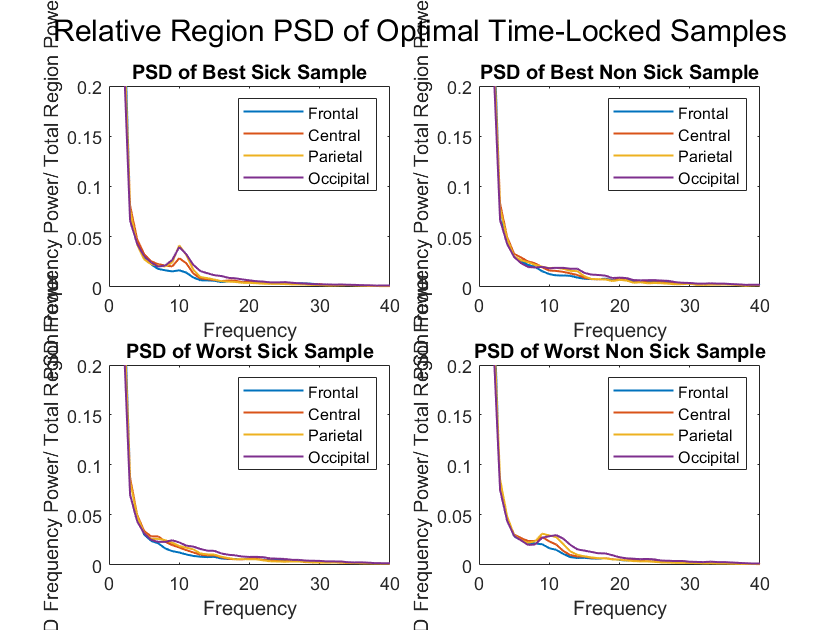

figure; % create a new figure
line_thickness = 1;
if (strcmp(dataset_type, 'roi'))
    title_section = 'Time-Locked';
else
    title_section = 'Filtered';
end

% Plot for matrix Sick
subplot(2,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(condition_arrays{1}, 1) % loop over rows
    plot(condition_arrays{1}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Best Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);
legend(labels);

subplot(2,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(condition_arrays{2}, 1) % loop over rows
    plot(condition_arrays{2}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Best Non Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);
legend(labels);

subplot(2,2,3); % Divide plot into 2 row, 1 columns, and select the first plot
for i = 1:size(condition_arrays{3}, 1) % loop over rows
    plot(condition_arrays{3}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Worst Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);
legend(labels);

subplot(2,2,4); % Divide plot into 2 row, 2 columns, and select the first plot
for i = 1:size(condition_arrays{4}, 1) % loop over rows
    plot(condition_arrays{4}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Worst Non Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);
legend(labels);

sgtitle(['Relative Region PSD of Optimal ', title_section, ' Samples']);

## Plot Relative Power Density Of Combined Regions (Single Channel)

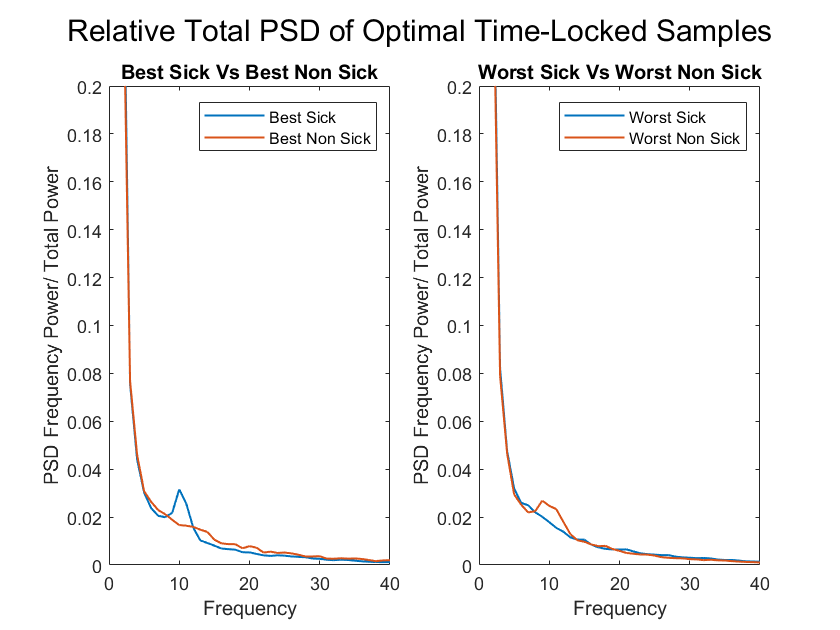

figure; % create a new figure
line_thickness = 1;
if (strcmp(dataset_type, 'roi'))
    title_section = 'Time-Locked';
else
    title_section = 'Filtered';
end

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
plot_data = mean(condition_arrays{1},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot

plot_data = mean(condition_arrays{2},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot

title('Best Sick Vs Best Non Sick');
ylabel('PSD {Frequency Power/ Total Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);
legend('Best Sick', 'Best Non Sick');


subplot(1,2,2); % Divide plot into 2 row, 1 columns, and select the first plot
plot_data = mean(condition_arrays{3},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot

title('Worst Sick Vs Worst Non Sick');
ylabel('PSD {Frequency Power/ Total Power}');
xlabel('Frequency');
ylim([0, 0.2]);
xlim([0, 40]);

plot_data = mean(condition_arrays{4},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
legend('Worst Sick', 'Worst Non Sick');

sgtitle(['Relative Total PSD of Optimal ', title_section, ' Samples']);

## Normality Test

% Get the normality check for ech participant
% true_difference_labels = {'true_sick', 'true_normal'};
% false_difference_labels = {'false_sick', 'false_normal'};
% 
% empty_array = [];
% 
% % Create the structure
% for i = 1:participant_no
%     n(i).true_diff.r1 = empty_array;
%     n(i).true_diff.r2 = empty_array;
%     n(i).true_diff.r3 = empty_array;
%     n(i).true_diff.r4 = empty_array;
%     
%     n(i).false_diff.r1 = empty_array;
%     n(i).false_diff.r2 = empty_array;
%     n(i).false_diff.r3 = empty_array;
%     n(i).false_diff.r4 = empty_array;
%     
% end
% 
% for participant = 1:participant_no
% 
%     % Get the region difference between best conditions/classes (Sick - Normal)
%     true_region_difference = cell2mat(struct2cell(p(participant).(true_difference_labels{1}))) - cell2mat(struct2cell(p(participant).(true_difference_labels{2}))); % Regions X f_length
% 
%     % Get the region difference between worst conditions/classes (Sick - Normal)
%     false_region_difference = cell2mat(struct2cell(p(participant).(false_difference_labels{1}))) - cell2mat(struct2cell(p(participant).(false_difference_labels{2}))); % Regions X f_length
% 
%     difference_cases = {true_region_difference, false_region_difference};
% 
%     for diff_case_id = 1:length(difference_cases)
%         
%     end
% 
% end



## Histogram

power_total = nan(1);
counts = nan(1);
for i = 1:participant_no
    region_arrays = cell2mat(struct2cell(p(i).(condition_index{2})));

    if ~isempty(region_arrays)
        power_10 = sum(region_arrays(:,20));
        power_total(i) =  power_10/4;   
    else
        power_total(i) = nan;
    end
    
end
figure;
histogram(power_total,29);
c_true_sick = 0;
c_true_normal = 0;
c_false_sick = 0;
c_false_normal = 0;

for i = 1:participant_no
    
    if ~isempty(cell2mat(struct2cell(p(i).(condition_index{1}))))
        c_true_sick = c_true_sick + 1;
    end
    if ~isempty(cell2mat(struct2cell(p(i).(condition_index{2}))))
        c_true_normal = c_true_normal + 1;
    end
    if ~isempty(cell2mat(struct2cell(p(i).(condition_index{3}))))
        c_false_sick = c_false_sick + 1;
    end
    if ~isempty(cell2mat(struct2cell(p(i).(condition_index{4}))))
        c_false_normal = c_false_normal + 1;
    end
end

c_true_sick 
c_true_normal 
c_false_sick
c_false_normal

# This is for maximization activation method

## Calculate the relative power of each participant for the 4 regions

clear;
dataset_type = 'roi';
load(['C:\Users\Abdulsatar\Documents\UBICOMP\Thesis Work\ReverseNeuro\Results\Plots\trial21\Kfold_', dataset_type ,'\trial6\maximization\matrix_jitter_output.mat']);
srate = 250;
nfft = srate;
f_length = (nfft/2) + 1;
participant_no = 29;
window_length = srate; % Size of the segments make to calculate PSD
overlap_length = 0; % Placing a 40% overlap between the segments
f = (0:1:40); % Frequencies of interest
f_channels = [4, 5, 6, 7, 8] - 3; % Frontal channels
c_channels = [9, 10, 11, 12, 13] - 3; % Central channels
p_channels =  [14, 15, 16] - 3; % Parietal channels
o_channels = [17, 18, 19] - 3; % Occipital channels

c_regions = {f_channels, c_channels, p_channels, o_channels};
region_index = {'r1', 'r2', 'r3', 'r4'}; % The region IDs used in the 'p' structure
condition_index = {'normal','sick'}; % The condition IDs used in the 'p' structure

empty_array = [];

% Create the structure
for i = 1:participant_no
    p(i).normal.r1 = empty_array;
    p(i).normal.r2 = empty_array;
    p(i).normal.r3 = empty_array;
    p(i).normal.r4 = empty_array;
    
    p(i).sick.r1 = empty_array;
    p(i).sick.r2 = empty_array;
    p(i).sick.r3 = empty_array;
    p(i).sick.r4 = empty_array;
    
end

%loop through each participant
for participant = 1:participant_no
    fieldName = ['field', num2str(participant)];
    %loop through each condition
    for condition = 1:length(condition_index)
        % Check if the condition is not empty (Has no samples)
        if ~isempty(export_matlab.(fieldName).(condition_index{condition}))
            % Get the samples if the respective condition
            samples = export_matlab.(fieldName).(condition_index{condition}); % 16X250X10 Channels X srate X Samples

            % Calculate the relative power of the samples
            % The relative power of the mean power of the samples is
            % calculated here
            [sp, fq] = relativePower(double(samples), window_length, overlap_length, nfft, srate, f_length); % Channels X nfft
            %loop through each region
            for region = 1:length(region_index)
                region_channels = sp(c_regions{region}, :); % Get the power of the channels in the respective region
                % Get the relative power in the region
                % The power is divided by the number if channels to account
                % for the different number of channels in a region
                p(participant).(condition_index{condition}).(region_index{region}) = sum(region_channels,1) / size(region_channels,1);
            end
        end
    end
end

## Get The Relative Power For The 2 Conditions

f = (0:1:40); % Frequencies of interest

% ARRAY TO HOLD SAMPLES
sick_array = []; % 16x250xM here M is the number of samples 
normal_array = []; % 16x250xM here M is the number of samples 

for participant = (1:participant_no)

    % GET THE SAMPLES
    % Get the sick and normal samples
    sick_sample = cell2mat(struct2cell(p(participant).(condition_index{2})));
    normal_sample = cell2mat(struct2cell(p(participant).(condition_index{1})));

    % Concatinate the samples
    sick_array = cat(3, sick_array, sick_sample);
    normal_array = cat(3, normal_array, normal_sample);
      
    
end

% Power in conditions
sick_power = sum(sick_array,3) / size(sick_array,3);
normal_power = sum(normal_array,3) / size(normal_array,3);


condition_arrays = {sick_power, normal_power};


labels = {'Frontal', 'Central', 'Parietal', 'Occipital'};

## Plot Relative Power Density Of Each Region

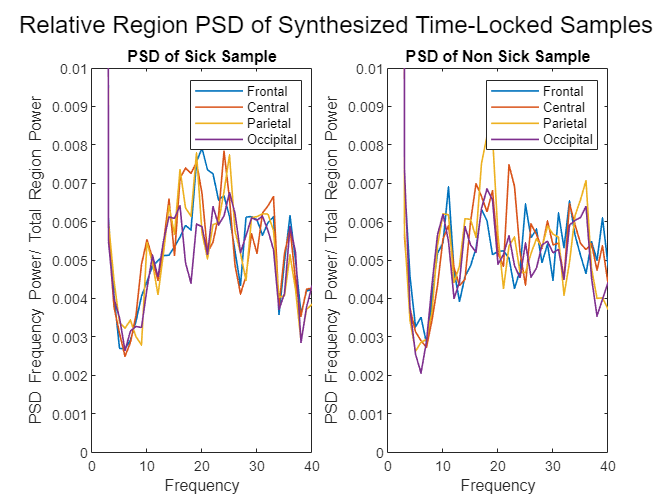

figure; % create a new figure
line_thickness = 1;
if (strcmp(dataset_type, 'roi'))
    title_section = 'Time-Locked';
else
    title_section = 'Filtered';
end

% Plot for matrix Sick
subplot(1,2,1); % Divide plot into 1 row, 1 columns, and select the first plot
for i = 1:size(condition_arrays{1}, 1) % loop over rows
    plot(condition_arrays{1}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.01]);
xlim([0, 40]);
legend(labels);

subplot(1,2,2); % Divide plot into 1 row, 2 columns, and select the second plot
for i = 1:size(condition_arrays{2}, 1) % loop over rows
    plot(condition_arrays{2}(i,:),'LineWidth', line_thickness); % plot each row on the same plot
    hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
end
title('PSD of Non Sick Sample');
ylabel('PSD {Frequency Power/ Total Region Power}');
xlabel('Frequency');
ylim([0, 0.01]);
xlim([0, 40]);
legend(labels);

sgtitle(['Relative Region PSD of Synthesized ', title_section, ' Samples']);

## Plot Relative Power Density Of Combined Regions (Single Channel)

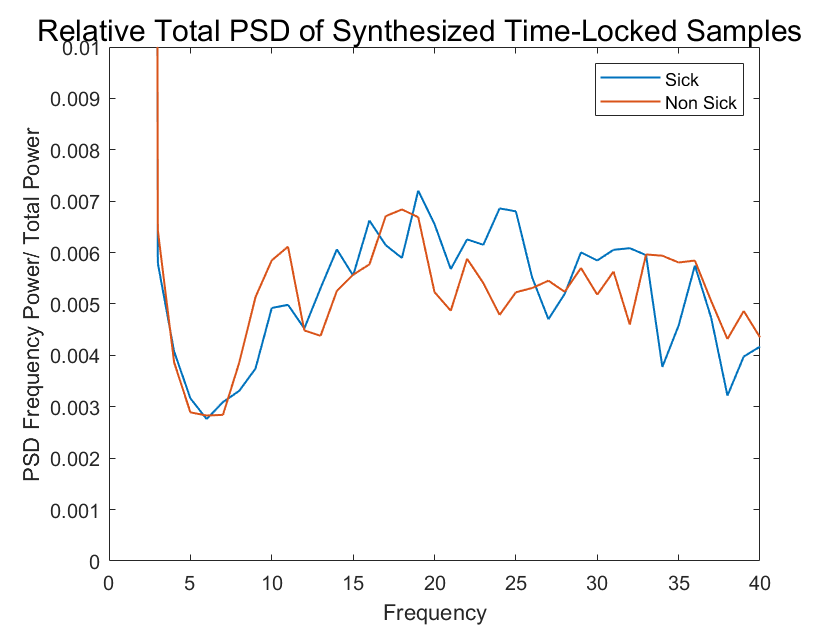

figure; % create a new figure
line_thickness = 1;
if (strcmp(dataset_type, 'roi'))
    title_section = 'Time-Locked';
else
    title_section = 'Filtered';
end

% Plot for matrix Sick
plot_data = mean(condition_arrays{1},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot

plot_data = mean(condition_arrays{2},1);
plot(plot_data,'LineWidth', line_thickness); % plot each row on the same plot
hold on; % holds the current plot and all its properties so that subsequent plot commands are added to the existing plot
ylabel('PSD {Frequency Power/ Total Power}');
xlabel('Frequency');
ylim([0, 0.01]);
xlim([0, 40]);

legend({'Sick', 'Non Sick'});

sgtitle(['Relative Total PSD of Synthesized ', title_section, ' Samples']);

function [power, frequency] = relativePower(samples, window_length, overlap_length, nfft, srate, f_length)
    % Function to calculate the relative power 
    epochs = size(samples,3);
    summed_spectra = zeros(size(samples,1), f_length); % The summed power of all the samples

    % Calculate summed power if samples
    for epoch = 1:epochs
        [sp, fq] = pwelch(samples(:,:, epoch)', window_length, overlap_length, nfft, srate);
        summed_spectra = summed_spectra + sp';
    end

    % Take into account the number of samples
    summed_spectra = summed_spectra / epochs;

    % Get the relative power
    total_power_per_channel = sum(summed_spectra,2);

    power = summed_spectra ./ total_power_per_channel;
    frequency = fq;
    
end